clear 
close all
clc
global K N frame_size distortion_eps

K=16; % number of clusters
N = 20; %number of MFCC features/ Mel filter banks
frame_size = 256;
distortion_eps = 0.05;

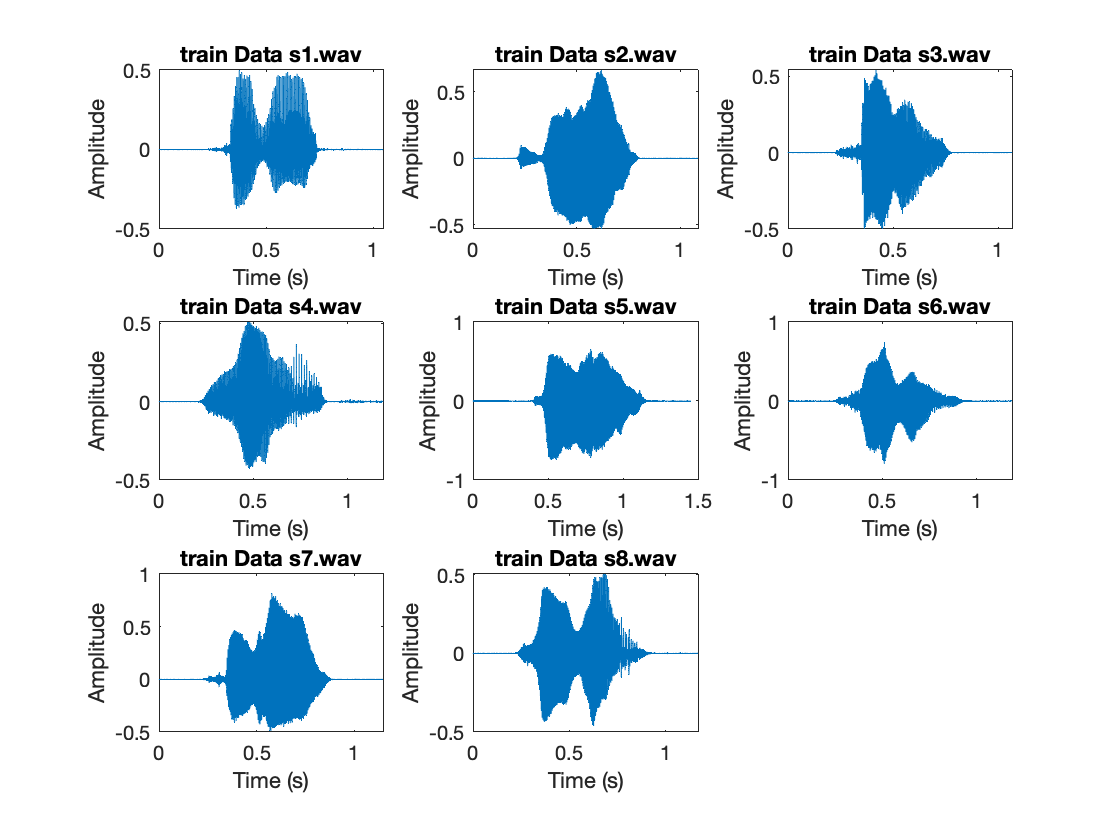

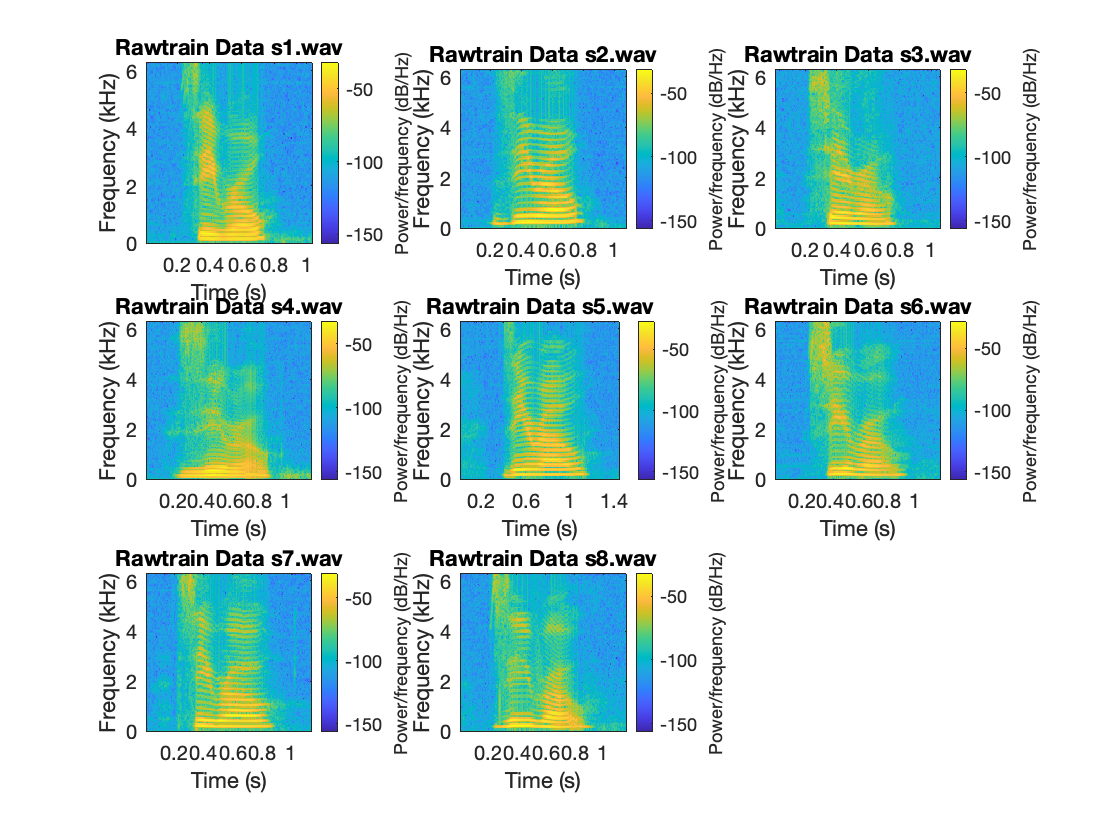

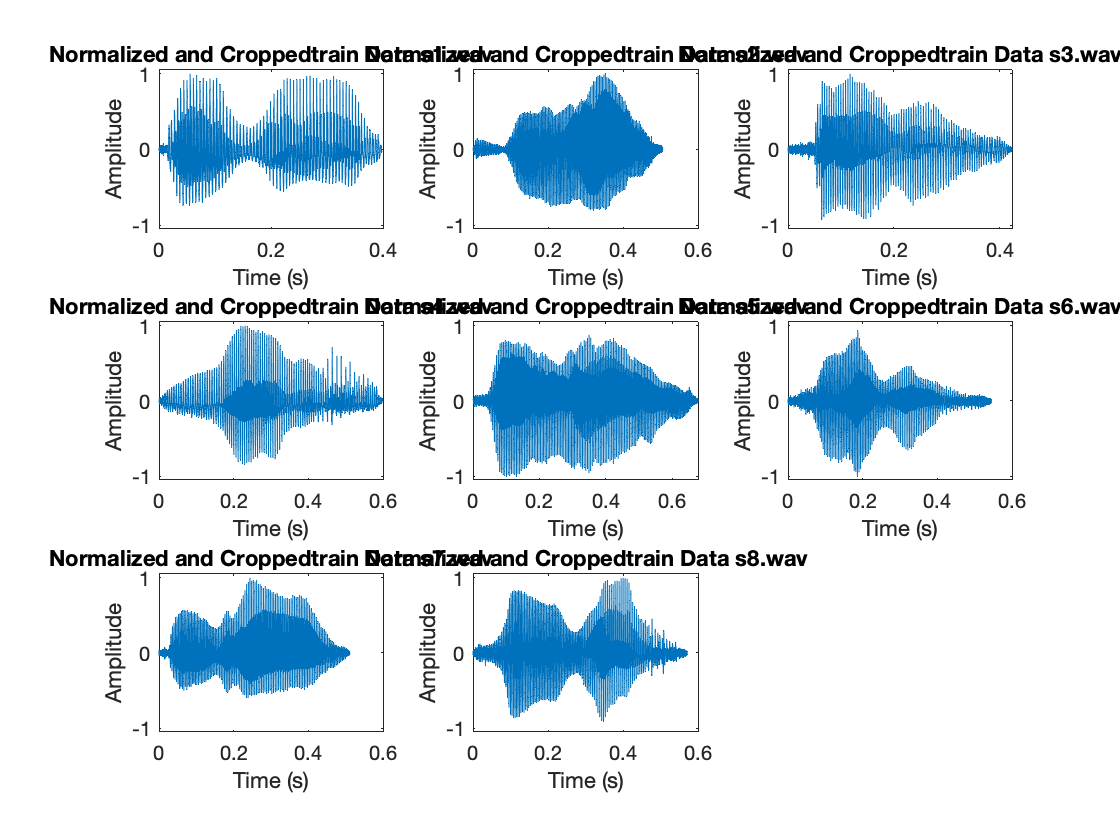

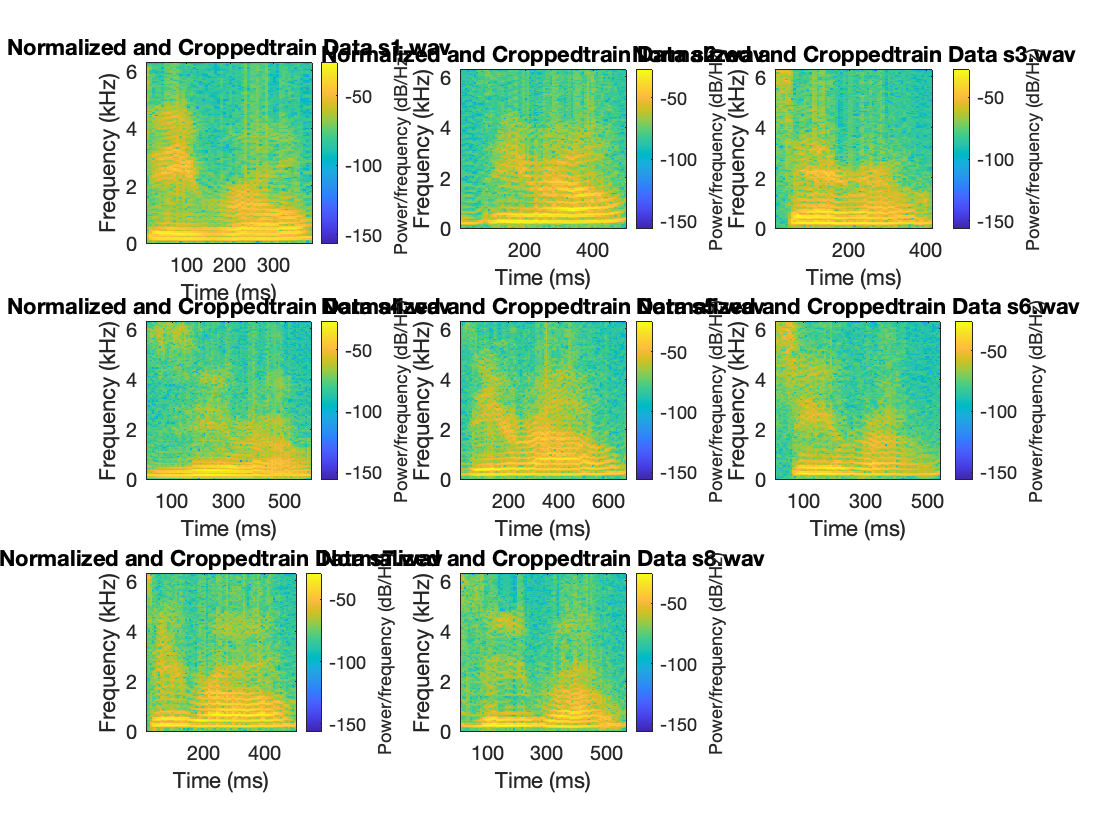

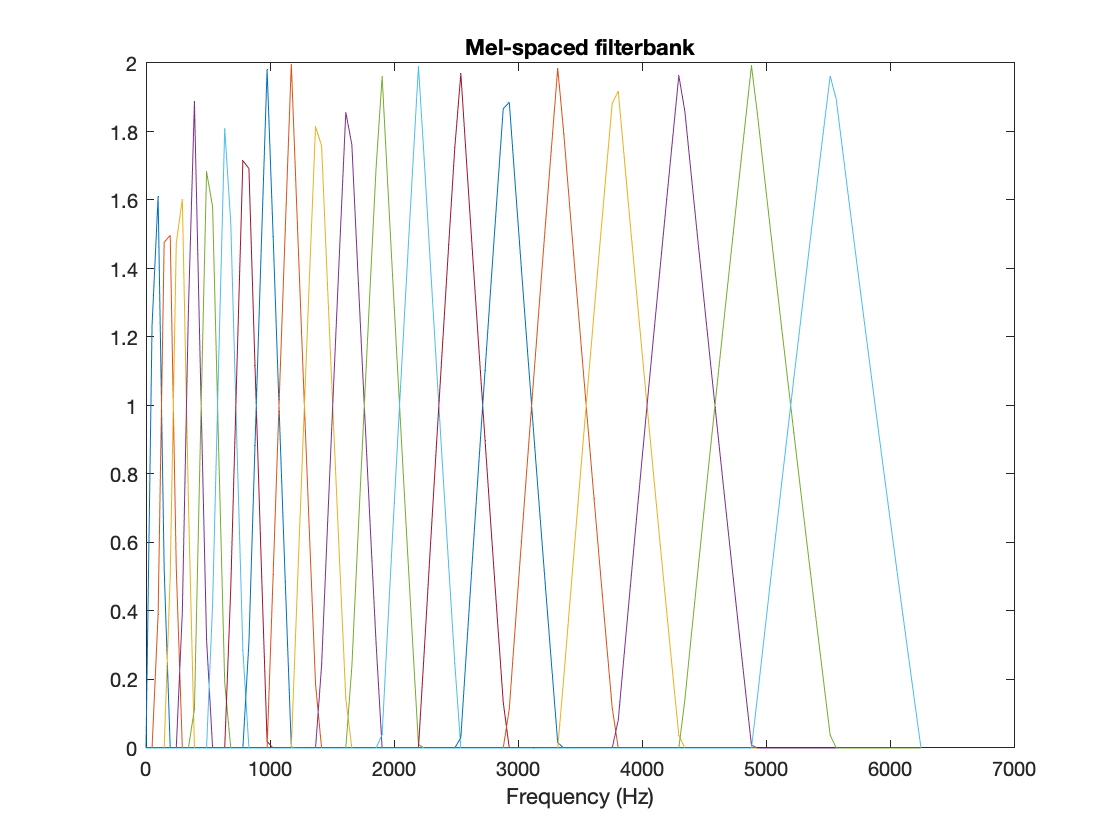

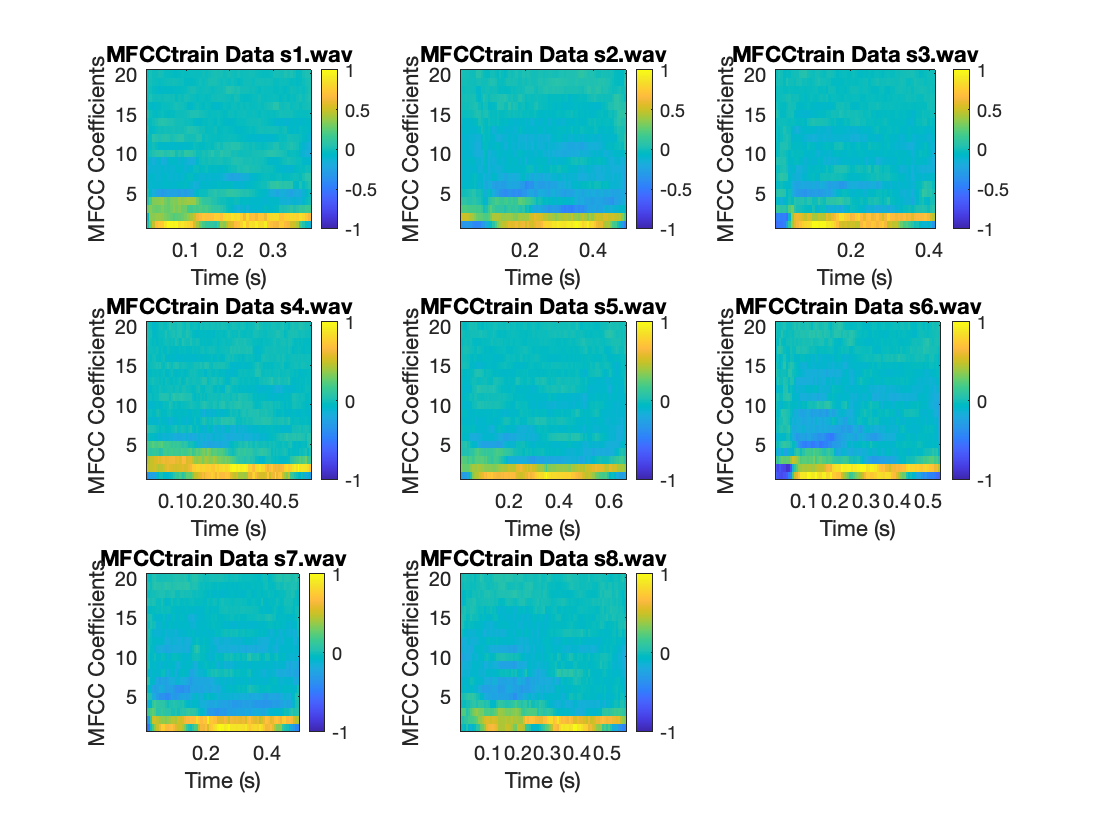

%%
% Train
verbose=1;
[cepstrum_train, t_out] = mfcc('train', 0, frame_size, N,verbose);

%% Determine Codebook
for i=1:size(cepstrum_train,2)
    [codebook{i}, clusterID{i}, D{i}] = LBG((cepstrum_train{i}(1:N,:))', K, distortion_eps);
end
%Remove NaN centroids, where no samples belong to a cluster
for i=1:size(cepstrum_train,2)
    codebook{i} = rmmissing(codebook{i});
end
%save codebook.mat codebook

%% Training Accuracy
% Load Ground Truth
T = readtable('./Data/Test_Data/ground_truth.csv','PreserveVariableNames',true);
ground_truth = T.("ground_truth");

codebook_size = size(codebook,2);
correct_guess=0;
thresh=0.12;
for i=1:size(cepstrum_train,2)
    [speaker_estimate_train{i},Distortion_train{i},clusterID_train{i}] = classify((cepstrum_train{i}(1:N,:))',codebook,codebook_size,thresh);

    if (speaker_estimate_train{i} == ground_truth(i))
        correct_guess = correct_guess + 1;
    end
end
training_acc = correct_guess/codebook_size*100;
%disp(strcat('Training Accuracy: ',num2str(training_acc),'%'))

% Test
verbose=0;
% Load Ground Truth
T = readtable('./Data/Test_Data/ground_truth.csv','PreserveVariableNames',true);
ground_truth = T.("ground_truth");

% Compute Cepstrum of Test Data
[cepstrum_test,t_test] = mfcc('test',0, frame_size,N,verbose);

% Test accuracy
codebook_size = size(codebook,2);
correct_guess=0;
thresh=0.12;
for i=1:size(cepstrum_test,2)
    [speaker_estimate_test{i},Distortion_test{i},clusterID_test{i}] = classify(cepstrum_test{i}',codebook,codebook_size,thresh);

    if (speaker_estimate_test{i} == ground_truth(i))
        correct_guess = correct_guess + 1;
    end
end
test_acc = correct_guess/size(cepstrum_test,2)*100;
disp(strcat('Training Accuracy on Canvas Dataset: ',num2str(training_acc),'%'))

Training Accuracy on Canvas Dataset:100%


disp(strcat('Testing Accuracy on Canvas Dataset: ',num2str(test_acc),'%'))

Testing Accuracy on Canvas Dataset:72.7273%


%disp('Performance on New dataset with additional "zero" recordings from 3 people:')

## New Dataset

TEST 7: Use the more voices ofyourself and your teammates/friend

% Train
verbose=0;
[cepstrum_train, t_out] = mfcc('train', 1, frame_size, N,verbose);
%% Determine Codebook
for i=1:size(cepstrum_train,2)
    [codebook{i}, clusterID{i}, D{i}] = LBG((cepstrum_train{i}(1:N,:))', K, distortion_eps);
end
%Remove NaN centroids, where no samples belong to a cluster
for i=1:size(cepstrum_train,2)
    codebook{i} = rmmissing(codebook{i});
end
%save codebook.mat codebook

%% Training Accuracy
% Load Ground Truth
T = readtable('./Data/Test_data_new/ground_truth.csv','PreserveVariableNames',true);
ground_truth = T.("ground_truth");

codebook_size = size(codebook,2);
correct_guess=0;
thresh=0.2;
for i=1:size(cepstrum_train,2)
    [speaker_estimate_train{i},Distortion_train{i},clusterID_train{i}] = classify((cepstrum_train{i}(1:N,:))',codebook,codebook_size,thresh);

    if (speaker_estimate_train{i} == ground_truth(i))
        correct_guess = correct_guess + 1;
    end
end
training_acc = correct_guess/codebook_size*100;
%disp(strcat('Training Accuracy: ',num2str(training_acc),'%'))

% Test
verbose=0;
% Load Ground Truth
T = readtable('./Data/Test_data_new/ground_truth.csv','PreserveVariableNames',true);
ground_truth = T.("ground_truth");

% Compute Cepstrum of Test Data
[cepstrum_test,t_test] = mfcc('test',1, frame_size,N,verbose);
% Test accuracy
codebook_size = size(codebook,2);
correct_guess=0;
thresh=0.2;
for i=1:size(cepstrum_test,2)
    [speaker_estimate_test{i},Distortion_test{i},clusterID_test{i}] = classify(cepstrum_test{i}',codebook,codebook_size,thresh);

    if (speaker_estimate_test{i} == ground_truth(i))
        correct_guess = correct_guess + 1;
    end
end
disp('Performance on New dataset with additional "zero" recordings from 3 people:')

Performance on New dataset with additional "zero" recordings from 3 people:


disp(strcat('Training Accuracy on New Dataset: ',num2str(training_acc),'%'))

Training Accuracy on New Dataset:100%


disp(strcat('Testing Accuracy on New Dataset: ',num2str(correct_guess/codebook_size*100),'%'))

Testing Accuracy on New Dataset:71.4286%
